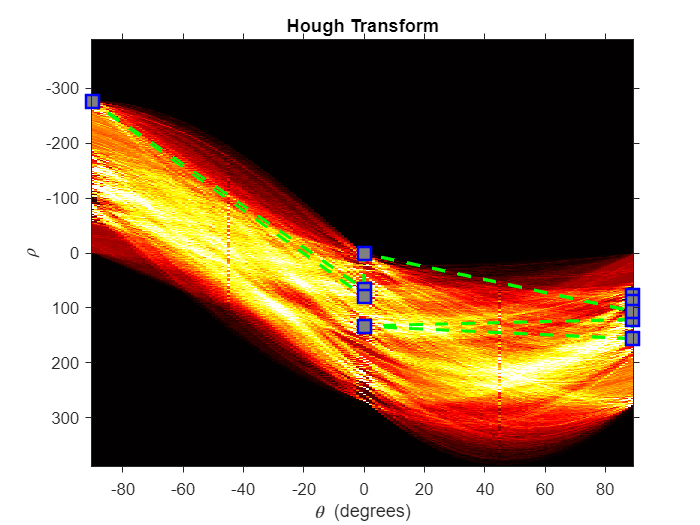

% Read an image into the workspace
image = imread('C:\Users\harsh\OneDrive\Desktop\UNT Subjects\Feature Engineering\Trials\pic2.png');

% Calling the detectLinesLength Function which returns the lines of Minimun
% length which is set and with the showImageWithLines the visualization is
% done
%  Function calling way -- detectLinesLength(image, minLength)
detectedLines = detectLinesLength(image, 60);

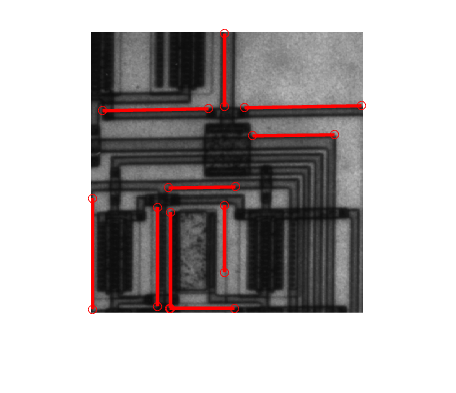

showImageWithLines(detectedLines,image);

%detectedLinesWithWidth = detectLinesLengthWidth(image, 20 ,1);
%showImageWithLines(detectedLinesWithWidth,image);
% Calling the detectLinesLength Function which returns the lines of Minimun
% length and width which is set and with the showImageWithLines the visualization is
% done
%  Function calling way -- detectLinesWithWidth(image, minLength, minWidth)
detectLineWithWidth = detectLinesWithWidth(image, 10, 1);

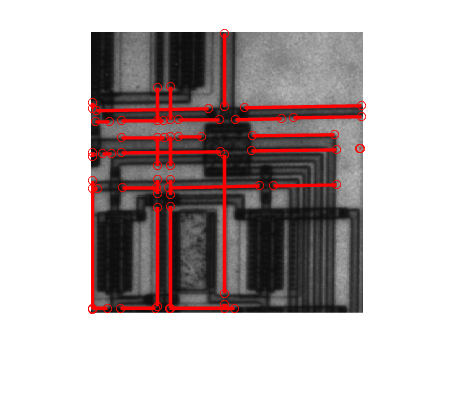

showImageWithLines(detectLineWithWidth,image);

This below function is used to detect lines with the minimun length specified

It takes the input -- image, length

function detectedLines = detectLinesLength(image, minLength)
    % Convert the image to grayscale
    grayImage = im2gray(image);
    BW = edge(grayImage,'canny');
    % Performing Hough transform to detect lines
    [H, theta, rho] = hough(BW);
    % Visualizing Hough space
    visualizeHoughspace(H, theta, rho);
    % Finding peaks using houghpeaks
    P = houghpeaks(H, 10);
    
    % Extract the lines from the Hough transform with min length
    detectedLines = houghlines(BW, theta, rho, P, 'FillGap', 5, 'MinLength', minLength);
end

%function detectedLinesWidth = detectLinesLengthWidth(image, minLength, minWidth)
    % Convert the image to grayscale
    %grayImage = im2gray(image);
    %BW = edge(grayImage, 'canny');
    
    % Perform the Hough transform to detect lines
    %[H, theta, rho] = hough(BW);
    
    % Find peaks in the Hough transform accumulator
    %P = houghpeaks(H, 10);
    
    % Extract the lines from the Hough transform
    %detectedLines = houghlines(BW, theta, rho, P, 'FillGap', 1, 'MinLength', minLength);
    
    % Filtering lines based on width
    %detectedLinesWidth = [];
    %for k = 1:length(detectedLines)
    %    if abs(diff(detectedLines(k).point1(1), detectedLines(k).point2(1))) >= minWidth
    %        detectedLinesWidth = [detectedLinesWidth; detectedLines(k)];
    %    end
    %end
%end

function detectedLines = detectLinesWithWidth(image, minLength, lineWidth)
    % Perform edge detection (you can adjust the parameters as needed)
    grayImage = im2gray(image);
    BW = edge(grayImage, 'Canny');

    % Perform Hough transform with custom LineWidth parameter
    [H, Theta, Rho] = hough(BW, 'RhoResolution', 1, 'ThetaResolution', 1);
    % Visualizing Hough space
    visualizeHoughspace(H, Theta, Rho);
    % Find peaks in the Hough transform
    P = houghpeaks(H, 10);

    % Get lines from the peaks with given LineWidth
    lines = houghlines(BW, Theta, Rho, P, 'FillGap', minLength, 'MinLength', lineWidth);
    detectedLines = lines;
end


function showImageWithLines(detectedLines,image)
    figure;
    imshow(image);
    hold on;
    
    % looping the detected lines and adding on top of the image
    for k = 1:length(detectedLines)
        xy = [detectedLines(k).point1; detectedLines(k).point2];
        plot(xy(:, 1), xy(:, 2), 'LineWidth', 2, 'Color', 'r');
        
        % Plotting end points on the image with circles
        plot(xy(1, 1), xy(1, 2), 'ro', 'MarkerSize', 5);
        plot(xy(2, 1), xy(2, 2), 'ro', 'MarkerSize', 5);
    end
    hold off;
end

% This below function is used to generate Hough space using the values
% generated by using hough transform function
function visualizeHoughspace(H, theta, rho)
    figure;
    imshow(imadjust(rescale(H)),[],...
           'XData',theta,...
           'YData',rho,...
           'InitialMagnification','fit');
    xlabel('\theta (degrees)')
    ylabel('\rho')
    title("Hough Transform");
    axis on
    axis normal 
    hold on
    colormap(gca,hot);
    P = houghpeaks(H,10);
    x = theta(P(:,2));
    y = rho(P(:,1));
    plot(x,y,'--gs',...
        'LineWidth',2,...
        'MarkerSize',10,...
        'MarkerEdgeColor','b',...
        'MarkerFaceColor',[0.5,0.5,0.5]);
end